# Homework 1

## Problem 9.1

refreshdata
n = [1 2 3 8];
d = 0.1;

ans = 1

ans = 2

ans = 3

ans = 8

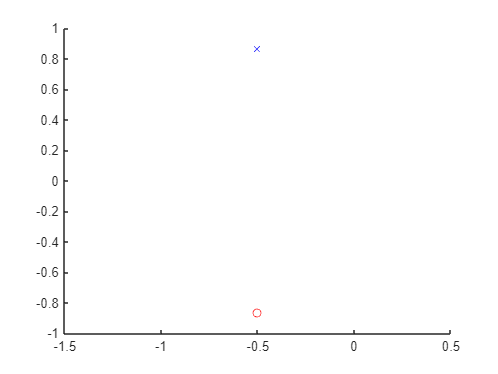

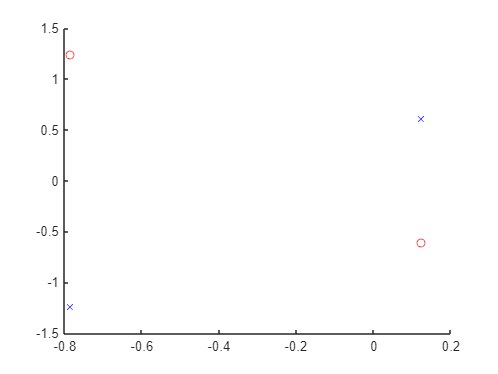

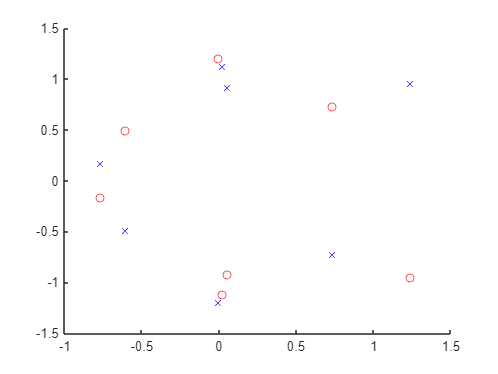


for i = [1 2 3 4]
    refreshdata
    k = pade(exp(-1*d*s),s,'Order',n(i)); %It was working, and then it decided to stop working after I changed nothing
    [num,den] = numden(k);
    p = int(coeffs(num));
    q = int(coeffs(den));
    o = roots(p);
    x = roots(q);
    figure(i) % it should be printing 4 figures, but there're only 3 so clearly Matlab is getting confused
    hold on
    plot(roots(o),'ro')
    plot(roots(x),'bx')
    hold off
end

% proof of concept
clear
refreshdata
syms s
n = [1 2 3 8];
d = 0.1;
F = exp(-1*d*s);

k = pade(F,s,'Order',8);
[num,den] = numden(k)

$$num = s^{8}-720\,s^{7}+252000\,s^{6}-55440000\,s^{5}+8316000000\,s^{4}-864864000000\,s^{3}+60540480000000\,s^{2}-2594592000000000\,s+51891840000000000$$

$$den = s^{8}+720\,s^{7}+252000\,s^{6}+55440000\,s^{5}+8316000000\,s^{4}+864864000000\,s^{3}+60540480000000\,s^{2}+2594592000000000\,s+51891840000000000$$

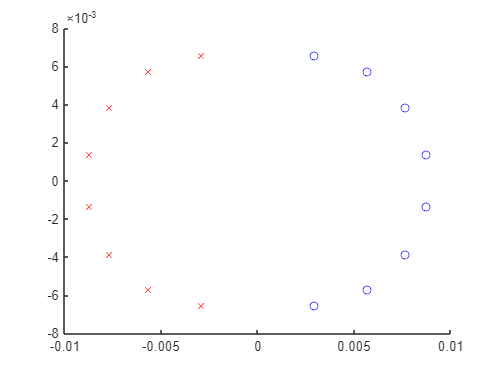

o = int(coeffs(num));
x = int(coeffs(den));
p = roots(o);
q = roots(x);

figure(5)
hold on
plot(p,'bo')
plot(q,'rx')
hold off

## Problem 9.12

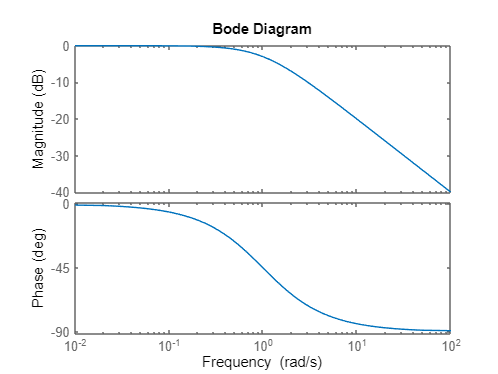

bode(tf([1],[1 1]))

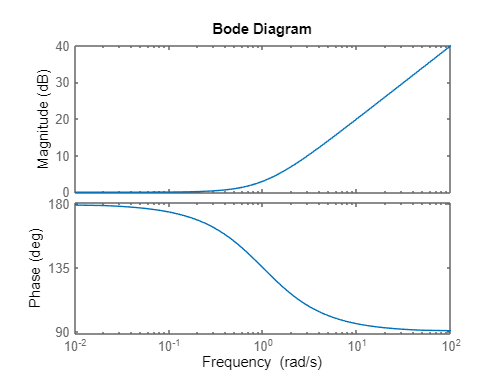

bode(tf([1 -1],[1]))

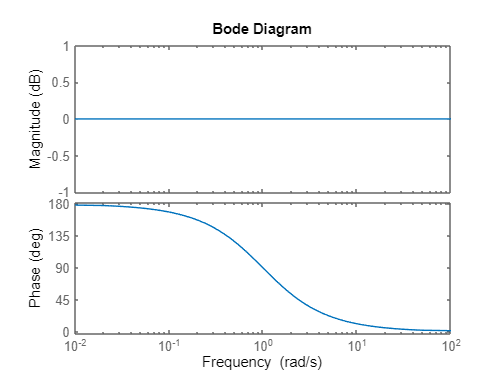

bode(tf([1 -1],[1 1]))

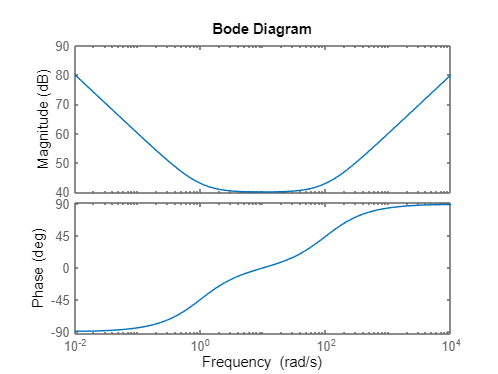

bode(tf([1 101 100],[1 0]))

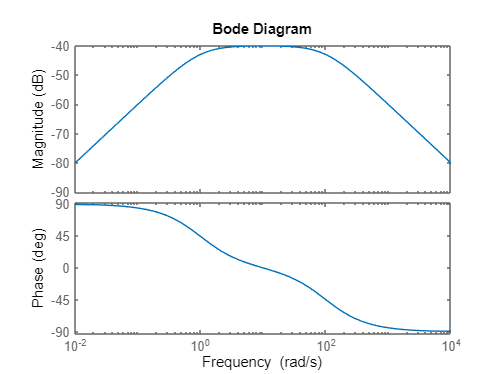

bode(tf([1 0],[1 101 100]))

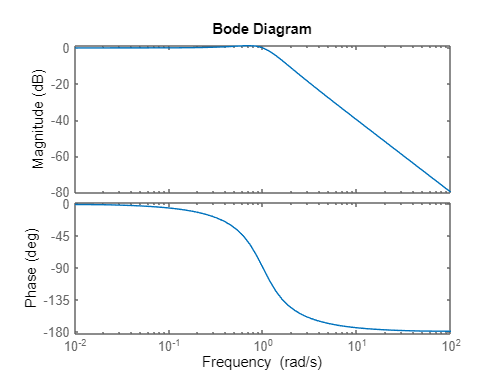

bode(tf([1],[1 1 1]))

## Problem 10.2

clear
syms L2 L5 s V0 
R1 =1e3; 
R4 =1e3; 
R3 =1e5;
A= [1 -1 -1 0 0 0 0 0 ; 0 1 0 -1 -1 0 0 0 ; 0 0 1 1 0 -1 0 0 ;
    0 R1 0 0 0 0 1 0 ; s*L2 0 -s*L2 0 0 0 0 1 ; 0 0 0 R3 0 0 -1 1 ;
    0 0 0 0 R4 0 -1 0 ; 0 0 0 0 0 -s*L5 0 1 ] 

$$A = \left(\begin{array}{cccccccc} 1 & -1 & -1 & 0 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & -1 & -1 & 0 & 0 & 0\\ 0 & 0 & 1 & 1 & 0 & -1 & 0 & 0\\ 0 & 1000 & 0 & 0 & 0 & 0 & 1 & 0\\ L_{2}\,s & 0 & -L_{2}\,s & 0 & 0 & 0 & 0 & 1\\ 0 & 0 & 0 & 100000 & 0 & 0 & -1 & 1\\ 0 & 0 & 0 & 0 & 1000 & 0 & -1 & 0\\ 0 & 0 & 0 & 0 & 0 & -L_{5}\,s & 0 & 1 \end{array}\right)$$

b = [ 0 ; 0 ; 0 ; V0 ; 0 ; 0 ; 0 ; 0 ] 

$$b = \left(\begin{array}{c} 0\\ 0\\ 0\\ V_{0}\\ 0\\ 0\\ 0\\ 0 \end{array}\right)$$

x =A\b

$$x = \begin{array}{l} \left(\begin{array}{c} \frac{V_{0}\,\left(101000\,L_{2}-100000\,L_{5}+L_{2}\,L_{5}\,s\right)}{\sigma_{1}}\\ -\frac{101\,V_{0}}{L_{2}\,s-201000}\\ \frac{V_{0}\,\left(101000\,L_{2}+1000\,L_{5}+L_{2}\,L_{5}\,s\right)}{\sigma_{1}}\\ -\frac{V_{0}\,\left(L_{2}\,s+1000\right)}{\sigma_{3}}\\ \frac{\sigma_{2}}{\sigma_{3}}\\ \frac{101\,L_{2}\,V_{0}}{L_{5}\,\left(L_{2}\,s-201000\right)}\\ \frac{\sigma_{2}}{L_{2}\,s-201000}\\ \frac{101\,L_{2}\,V_{0}\,s}{L_{2}\,s-201000} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=1000\,L_{5}\,\left(L_{2}\,s-201000\right)\\ \sigma_{2}=V_{0}\,\left(L_{2}\,s-100000\right)\\ \sigma_{3}=1000\,\left(L_{2}\,s-201000\right) \end{array}$$

## Problem 10.5

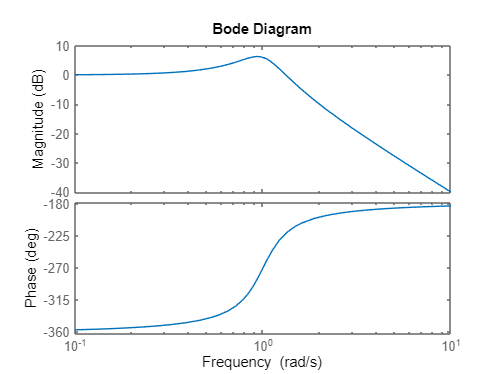

bode(tf([1],[1 -0.5 1]))